Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz behind.WAV...


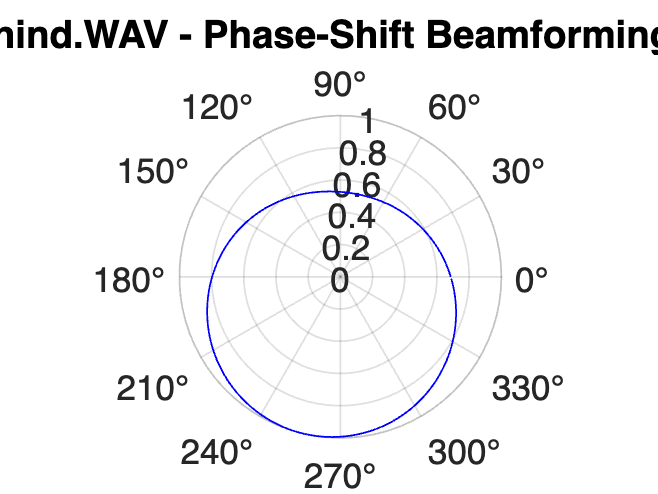

Max energy at 257.0 degrees (value = 1.00)



Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz left.WAV...


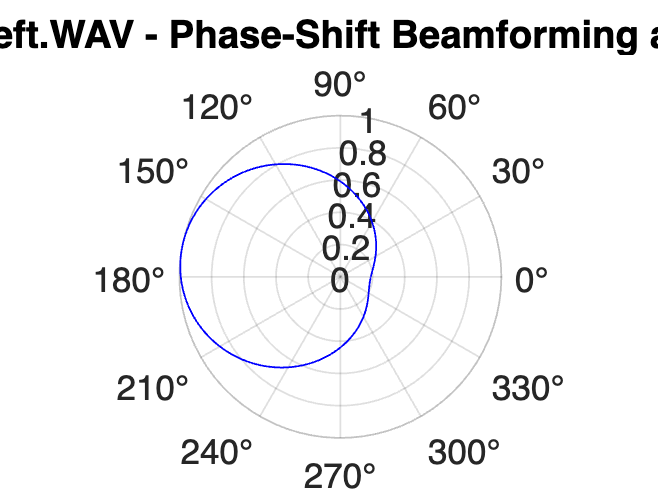

Max energy at 170.0 degrees (value = 1.00)



Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hz right.WAV...


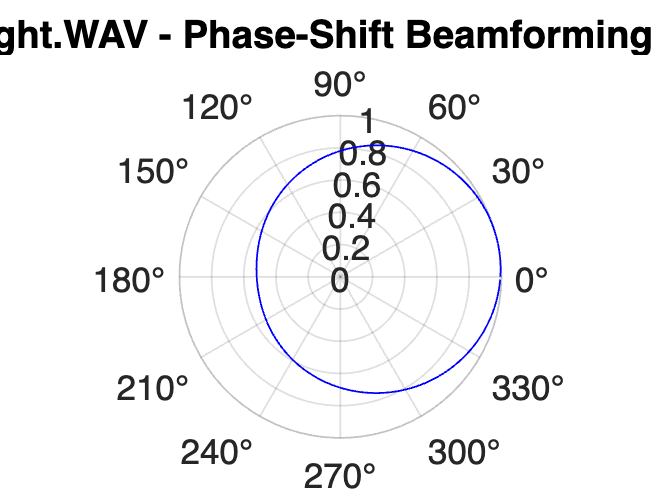

Max energy at 12.0 degrees (value = 1.00)



Processing /Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz/700hzfront.WAV...


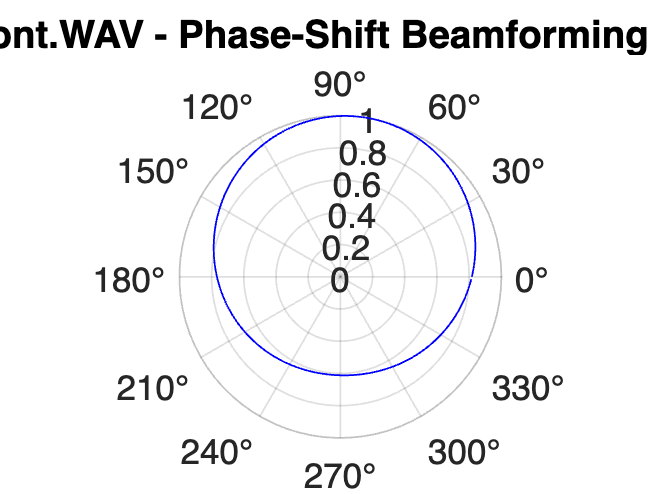

Max energy at 81.0 degrees (value = 1.00)



%beamforming _freq domain_hanning window 

% Parameters 
fs = 32000;           
c = 343;                
d = 0.06;             
mic_positions = [0, 0; d, 0; d, d; 0, d];  % 4 mics: clockwise square
angles = 0:1:359;       
N = 4096;               
f0 = 700;              
bandwidth = 100;        % ±50 Hz around target


base_folder = '/Users/macos/Documents/MATLAB/Simulation_capstone/dataset/at home/700hz';
file_pattern = fullfile(base_folder, '**/*.wav');  
wav_files = dir(file_pattern);

if isempty(wav_files)
    error('No WAV files found in the specified directory.');
end


for i = 1:length(wav_files)
    audio_file = fullfile(wav_files(i).folder, wav_files(i).name);
    fprintf('Processing %s...\n', audio_file);
    [audio, fs] = audioread(audio_file);
    
    if size(audio, 2) ~= 4
        error('Expected 4-channel WAV file.');
    end
    
    % Extract a frame of audio for beamforming
    frame = audio(1:N, :);
    
    % Perform frequency-domain beamforming
    powers = freq_domain_beamforming(frame, fs, mic_positions, angles, c, N, f0, bandwidth);
    
    % Plot the result
    figure;
    polarplot(deg2rad(angles), powers, 'b');
    title(sprintf('%s - Phase-Shift Beamforming at %d Hz', wav_files(i).name, f0), 'Interpreter', 'none');
    
    % Print the max angle
    [max_val, idx] = max(powers);
    max_angle = angles(idx);
    fprintf('Max energy at %.1f degrees (value = %.2f)\n\n', max_angle, max_val);
end

function powers = freq_domain_beamforming(frame, fs, mic_positions, angles, c, N, f0, bandwidth)
% freq_domain_beamforming - Perform phase-shift beamforming in frequency domain
%
% INPUTS:
%   frame        - Audio frame (Nx4) for 4 microphones
%   fs           - Sampling rate (Hz)
%   mic_positions - 4x2 matrix of microphone positions [x, y]
%   angles       - Array of beamforming angles (degrees)
%   c            - Speed of sound (m/s)
%   N            - FFT length
%   f0           - Target frequency (Hz)
%   bandwidth    - Frequency range (± around f0)
%
% OUTPUT:
%   powers       - Beamformed power for each angle (normalized)

% Apply Hann window and compute FFT 
frame = frame .* hann(N);   % Apply Hann window
X = fft(frame, N);          % FFT of each channel
f_axis = (0:N-1) * fs / N;  % Frequency axis

% Frequency bins of interest
bins = round((f0 - bandwidth/2) / fs * N) : round((f0 + bandwidth/2) / fs * N);

%Initialize power array
powers = zeros(size(angles));

%Beamforming across angles 
for i = 1:length(angles)
    theta = deg2rad(angles(i));
    direction = [cos(theta), sin(theta)];
    delays = mic_positions * direction' / c;  % time delays [4x1]
    
    energy = 0;
    for b = bins
        if b > N  % Avoid out of range
            continue;
        end
        
        f_b = f_axis(b);
        X_f = X(b, :).';  % [4 x 1] - FFT values at this frequency for each mic
        phase_shifts = exp(-1j * 2 * pi * f_b * delays);  % [4 x 1]
        y = sum(X_f .* phase_shifts);  % scalar beamforming result
        energy = energy + abs(y)^2;  % accumulate power
    end
    
    powers(i) = energy;
end

%Normalize power for better visualization
powers = powers / max(powers);
end
